# SysMIC M1: Assignment 2

If you need help for this assignment please make use of the [session 2 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2523).

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2349.](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2349.)

After submission you can access model answers via the [session 2 review](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=3197) activity.

`NAME: Jade Lau`

## Exercise 2.1.5

Q2. Look at adjacency matrix 

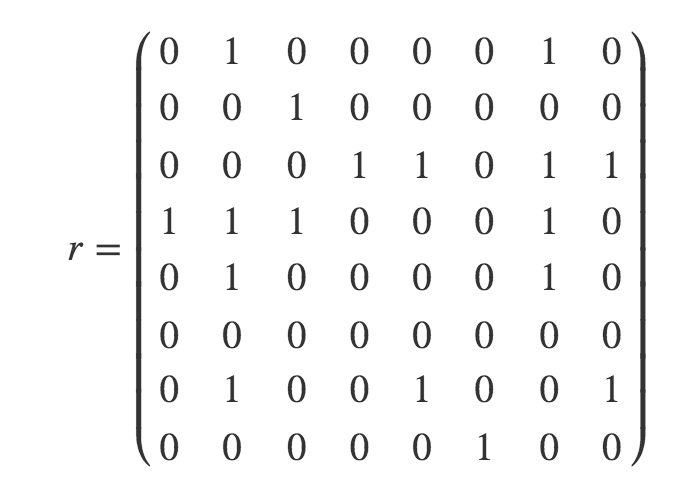

i) Define matrix `r` in MATLAB.

ii) How many nodes and edges are in the graph `r` represents?

iii) Draw the graph using MATLAB and choose a suitable layout.

**2.1.5 Q2 part i)**

r = [0 1 0 0 0 0 1 0;
     0 0 1 0 0 0 0 0;
     0 0 0 1 1 0 1 1;
     1 1 1 0 0 0 1 0;
     0 1 0 0 0 0 1 0;
     0 0 0 0 0 0 0 0;
     0 1 0 0 1 0 0 1;
     0 0 0 0 0 1 0 0;
     ];



**2.1.5 Q2 part ii)**

%8 nodes, 17 edges




**2.1.5 Q2 part iii)**

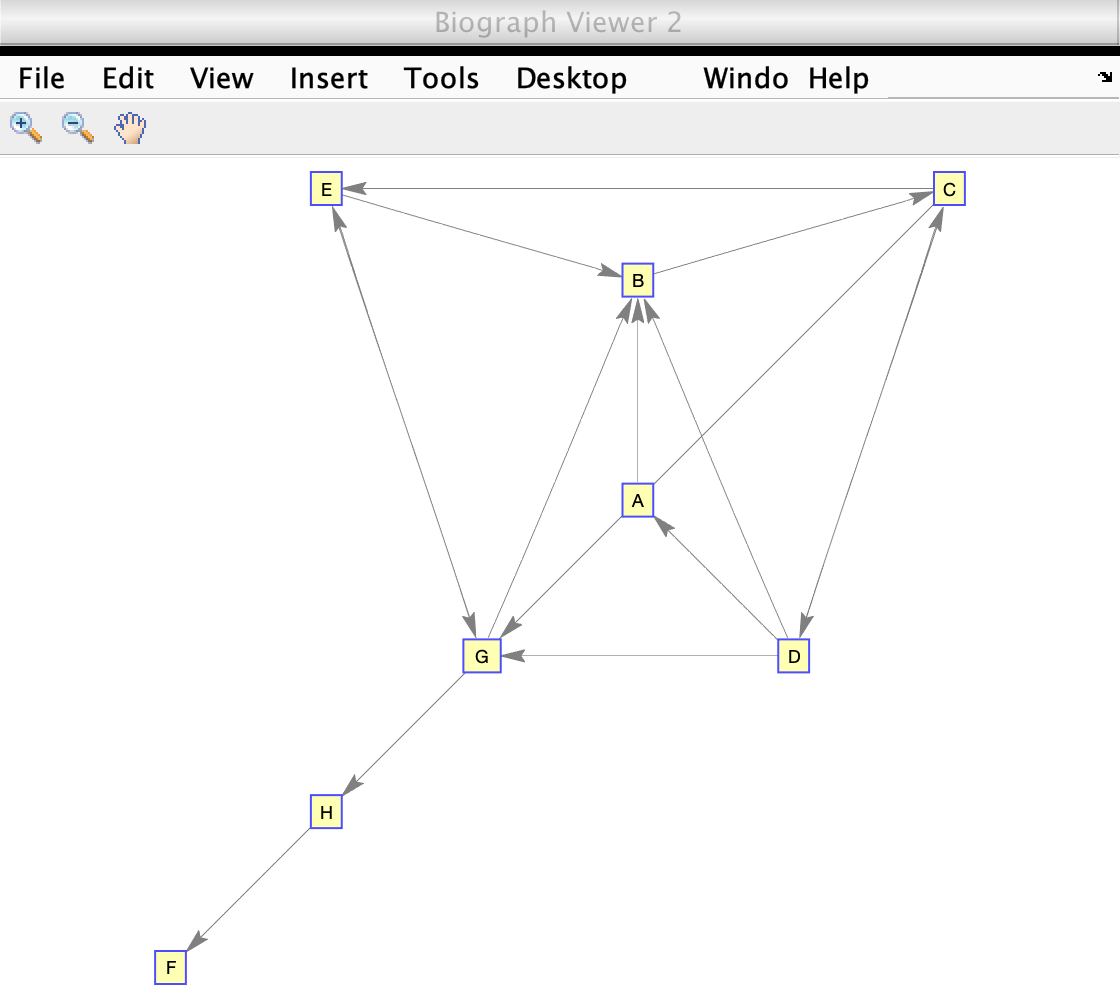

Biograph object with 8 nodes and 17 edges.


r_nodes = {'A' 'B' 'C' 'D' 'E', 'F' 'G' 'H'};
rg = biograph(r,r_nodes);
rg.LayoutType = 'radial';
dolayout(rg);
rvg = view(rg)

## Exercise 2.1.6

Q1) Draw the soil biota food web given at the start of this example, ignoring the two arrows on the left of the food web that do not end on a particular species. Experiment with the different layout algorithms and the node color and shape.

Hint:

- Using pen and paper, draw a diagram of the food web.

- Decide on the ordering of the nodes. I chose to order via trophic level (size of fauna) and then left to right. (**Hint:** There are 12 nodes in total.)

- Label your pen and paper diagram with the node numbers.

- Work out all the edges in the graph. Note the numbers of the node at the start of the edge and the node at the end of the edge. (**Hint:** There are 14 edges in total.)

- Define a 12××12 matrix in MATLAB using the `zeros` function.

- For each edge, set the corresponding entry in the matrix to 1 (start node number corresponds to row number and end node number corresponds to column number in the adjacency matrix).

- Define a cell array containing your node names and create a biograph object.

- Experiment with the layout, colours, node shapes etc.

Remember to use the MATLAB documentation, e.g. using `doc` if you have problems (or alternatively use a search engine such as Google).

To save the graph as an image file, in the "File" menu (top right of the biograph viewer) select "Print to figure", which opens a normal MATLAB figure. There, in the "File" menu select "Save as" and pick the file format in the dropdown menu for Format.

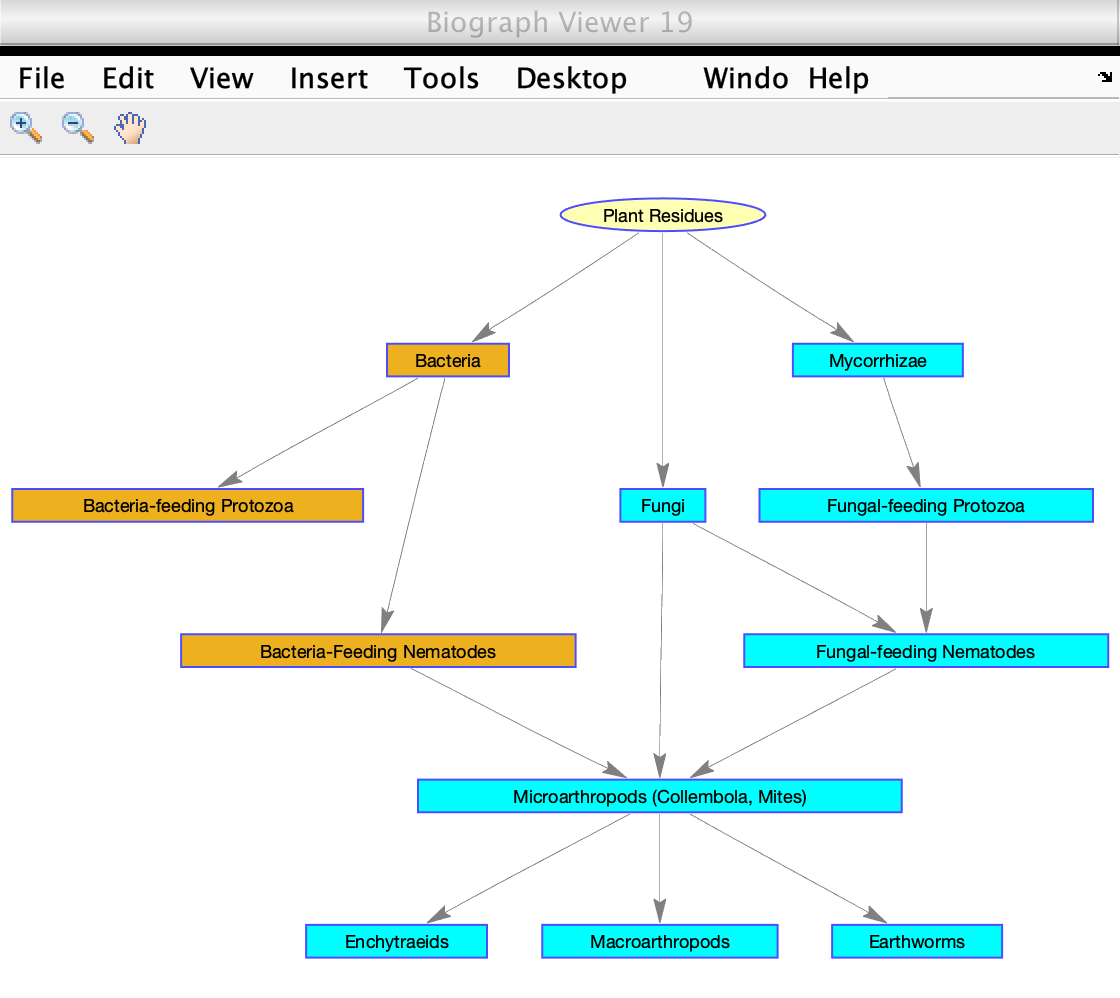

     %1 2 3 4 5 6 7 8 9 0 1 2
fw = [0 1 0 0 1 0 1 0 0 0 0 0; %1Plant res
      0 0 1 1 0 0 0 0 0 0 0 0; %2bact
      0 0 0 0 0 0 0 0 0 0 0 0; %3bact prot
      0 0 0 0 0 0 0 0 1 0 0 0; %4bact nema
      0 0 0 0 0 1 0 0 1 0 0 0; %5fungi
      0 0 0 0 0 0 0 0 1 0 0 0; %6fungi nema
      0 0 0 0 0 0 0 1 0 0 0 0; %7myco
      0 0 0 0 0 1 0 0 0 0 0 0; %8fungi pro
      0 0 0 0 0 0 0 0 0 1 1 1; %9micro
      0 0 0 0 0 0 0 0 0 0 0 0; %0enchy
      0 0 0 0 0 0 0 0 0 0 0 0; %1macro
      0 0 0 0 0 0 0 0 0 0 0 0; %2earth
     
     ];
nodes = {'Plant Residues'
         'Bacteria'
         'Bacteria-feeding Protozoa'
         'Bacteria-Feeding Nematodes'
         'Fungi' 
         'Fungal-feeding Nematodes'
         'Mycorrhizae'
         'Fungal-feeding Protozoa'
         'Microarthropods (Collembola, Mites)'
         'Enchytraeids'
         'Macroarthropods'
         'Earthworms'
         };
     
g = biograph(fw,nodes);
% g.LayoutType = '';
dolayout(g);
vg = view(g);

set(vg.nodes(1),'Shape','Circle');

set(vg.nodes(2),'Color',[0.9290, 0.6940, 0.1250]);
set(vg.nodes(3),'Color',[0.9290, 0.6940, 0.1250]);
set(vg.nodes(4),'Color',[0.9290, 0.6940, 0.1250]);

set(vg.nodes(5),'Color',[0 1 1]);
set(vg.nodes(6),'Color',[0 1 1]);
set(vg.nodes(7),'Color',[0 1 1]);
set(vg.nodes(8),'Color',[0 1 1]);
set(vg.nodes(9),'Color',[0 1 1]);
set(vg.nodes(10),'Color',[0 1 1]);
set(vg.nodes(11),'Color',[0 1 1]);
set(vg.nodes(12),'Color',[0 1 1]);